# Pruebas de Adaline

### Filtro ADALINE 

%Empezamos añadiendo el path a las funciones de activación 
addpath("G:\Mi unidad\MCC\Primer Semestre\Inteligencia artificial\Codigos\Funciones de activacion");
%Definimos nuestro filtro adalind con una longitud de retraso de 4
delay = 6;
filter = ADALINEFilter(delay);

Vamos a darle una señal para ver que tal logra seguirla, casí estoy seguro de que esta propiedad se debe a que el filtro logra aproximar en forma lineal localmente a la función, algo así como una derivada. 

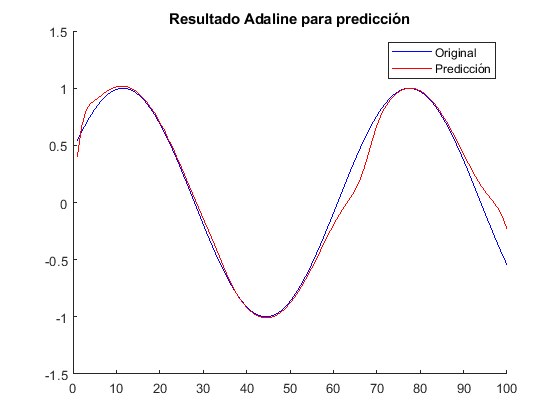

n = 100;
x = linspace(0,10,delay+n);
y = sin(x);
delaySig = y(1:delay);
sig = y(delay+1:end);

[filter,tracking] = filter.predictSignal(delaySig,sig,0.2);

figure()
title("Resultado Adaline para predicción")
hold on 
plot(sig,'color','b')
plot(tracking,'color','r')
hold off
legend("Original", "Predicción")

Es un poco claro de la figura que el resultado depende de que tanto esté cambiando la función en el punto en que se hace la predicción. Las mejores predicciones se logran para los puntos donde casí no hay cambio, que corresponderían a los valles y crestas de la función seno. 